## Planarizer DAQ

This program is responsible for establishing a UART connection with the Planarizer DAQ and sending/receiving data. 

### Required files and addons:

- **getAsyncKeyState.m** - used to obtain user inputs through the command window. If it is desired, refer to the license.txt and VirtualKeyCode.m for usage of this script 

- **user32.h** - a C file necessary to use getAsyncKeyState.m

- **MATLAB Support for MinGW-w64C/C++ Compiler **- this addon allows us to make use of getAsyncKeyState.m

### Usage

To **start** program:

Press "Run", and whenever you are ready to take data, go to the command window in             MATLAB and press any key. The program takes sometime to setup, so waiting until it the figure window pops up may be necessary before beginning the program. *If there are any issues, press the black reset button on the Arduino Shield, use delete(s) in the command window to close the serialport, and restart the program.*

Once the program has begun, you may use keyboard presses in the command window to do various things. 

'g' key        - Begin data collection

'esc' key    - End data collection and save data. This will also exit the program.

'p' key        - Begin ping test

's' key        - End ping test

*To begin another mode, the current mode must be exited first.*

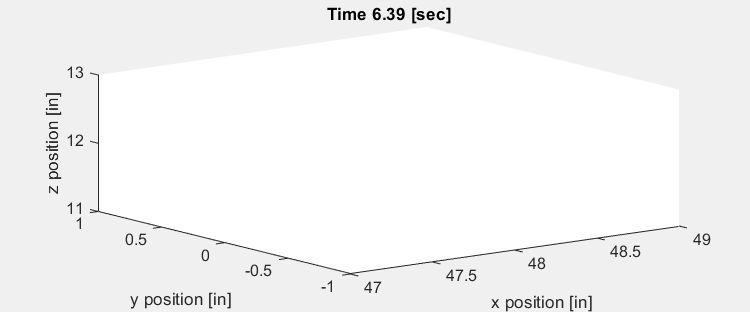

format long; clear output;

%Open serial port
COMport = 'COM8';
s=serialport(COMport, 115200); %start serial port 
s.Timeout = 10;
configureTerminator(s,"CR/LF", "CR");

prealloc = 9000000;

%Preallocated arrays for raw data
rp = 1; rawpitch = strings([prealloc,1]);
ry = 1; rawyaw = strings([prealloc,1]);

%Preallocated arrays for filtered data
yaw = zeros(prealloc,1); y = 1;
pitch = zeros(prealloc,1); p = 1;
pitch_time = zeros(prealloc,1); tplot = 1;
yaw_time = zeros(prealloc,1);
pitch_crc = zeros(prealloc,1);
yaw_crc = zeros(prealloc,1);

% Preallocated arrays for calculated data
Px = zeros(prealloc,1);
Py = zeros(prealloc,1);
Pz = zeros(prealloc,1);

% Length from planarizer base to point of interest along boom axis
l = 48;
% Length from Planarizer base to neutral axis of double booms
delt = 12.11;

corruption = 0; %amount of corrupted data, allows us to count how 
                %much data that can be identified as Pitch or Yaw first
                %fail the crc test or spit out inconherent characters

n = 1; %consolidated data index
Pmatch = zeros(prealloc,1); %preallocated pitch for consolidated data set
Ymatch = zeros(prealloc,1); %preallocated yaw for consolidated data set
Tmatch = zeros(prealloc,1); %preallocated time for consolidated data set
LOOKATY = 1; %index to look at yaw for data matching algorithm
LOOKATP = 1; %index to look at pitch for data matching algorithm
gonext = 0; %counter for when to give up on looking for a match

figure('Name','2DOF-TEST','Position', [150,0, 600, 250]);
set(gcf,'Visible','on') %open figure window 
plotted = 0; %counter for how many points have been plotted

% Wait here until a key is pressed in the command window
pause;

while y <= prealloc && p <= prealloc
    %check for user input
    if getAsyncKeyState(VirtualKeyCode.VK_ESCAPE)
        writeline(s,"r");
        %close the serial port line to avoid errors when restarting the
        %program
        delete(s);
        break;
    elseif getAsyncKeyState(VirtualKeyCode.VK_G) %to begin data collection
        writeline(s,"g");
    elseif getAsyncKeyState(VirtualKeyCode.VK_P) %to begin ping mode
        writeline(s,"p");        
    elseif getAsyncKeyState(VirtualKeyCode.VK_S) %to exit ping mode
        writeline(s,"s");           
    end

    % Reading data from serial port 
    C = readline(s);
    %split line using ':' and remove surrounding whitespace 
    c_str = strip(regexp(C, ',', 'split')); 
    if string(c_str(1)) == 'Yaw' 
        %get just the part following 'Yaw:'
        stripped = strip(regexp(C, 'Yaw,', 'split')); 
        rawyaw(ry) = stripped(2);
        %check if there are even four strings like there should be
        if length(c_str) == 4 
            %check if any of those strings are corrupted
            if isnan(str2double(c_str(2))) || isnan(str2double(c_str(3))) || isnan(str2double(c_str(4))) 
                corruption = corruption+1;
            %verify checksum
            elseif  str2double(c_str(2)) + str2double(c_str(3)) == str2double(c_str(4))
                %if all checks are passed, then data is deemed to be good
                yaw(y) = str2double(c_str(2));
                yaw_time(y) = str2double(c_str(3));
                yaw_crc(y) = str2double(c_str(4));
                y = y + 1;
            end
        end
        ry = ry+1; 

    elseif string(c_str(1)) == 'Pitch' 
        %get just the part following 'Pitch:' 
        stripped = strip(regexp(C, 'Pitch,', 'split')); 
        rawpitch(rp) = stripped(2);
        %check if there are even four strings like there should be
        if length(c_str) == 4 
            %check if any of those strings are corrupted
            if isnan(str2double(c_str(2))) || isnan(str2double(c_str(3))) || isnan(str2double(c_str(4))) 
                corruption = corruption+1;
            %verify checksum
            elseif  str2double(c_str(2)) + str2double(c_str(3)) == str2double(c_str(4))
                %if all checks are passed, then data is deemed to be good
                pitch(p) = str2double(c_str(2));
                pitch_time(p) = str2double(c_str(3));
                pitch_crc(p) = str2double(c_str(4));
                p = p + 1;    
            end
        end
        rp = rp+1;
    end

    %will use this value to compare later and check if 
    %new data was added to consolidated set
    plotflag = n; 
    
    %Consolidating pitch and yaw into a set of time matched data
    if min([y,p]) < 10    
        %do nothing
    elseif abs(yaw_time(LOOKATY)-pitch_time(LOOKATP)) < 5
        Pmatch(n) = pitch(LOOKATP);
        Ymatch(n) = yaw(LOOKATY);
        Tmatch(n) = yaw_time(LOOKATY);
        %Prepare for next search cycle
        LOOKATY = LOOKATY + 1;
        LOOKATP = LOOKATP + 1;
        gonext = 0;
        n=n+1;        
    elseif gonext >=10 
        %If we look too far ahead, and don't get a match,
        %there probably isn't one
        LOOKATY = LOOKATY + 1;
        LOOKATP = LOOKATP - 10;
        gonext = gonext - 10;
    else 
        %look at the next pitch value
        LOOKATP = LOOKATP +1;
        gonext = gonext + 1;
    end


    % Plot and process data
    if plotflag < n
        %calculate position
        r = l*cosd(Pmatch(n-1));
        Px(n-1) = r*cosd(Ymatch(n-1));
        Py(n-1) = r*sind(Ymatch(n-1));
        Pz(n-1) = l*sind(Pmatch(n-1)) + delt;
        tplot = tplot+1;
        %update plot every six data points to conserve processing time
        %currently at six points instead of more for better viewing
        %experience
        if tplot >= 6 
            plot3(Px(1:(n-1)),Py(1:(n-1)),Pz(1:(n-1)));
            time = Tmatch(n-1)/1000;
            text = sprintf('Time %0.2f [sec]', time);
            title(text);
            xlabel('x position [in]');
            ylabel('y position [in]');
            zlabel('z position [in]');
            drawnow
            plotted = plotted + 1;
            %reset counter
            tplot = tplot-6; 
        end
    end 
end

    
%put all of the raw yaw data into a table to save to a .txt file
Rawyawdata = table (rawyaw(1:ry));
Rawyawdata.Properties.VariableNames = {'yaw [deg], yaw_time [ms], yaw_crc'};

%put all of the raw pitch data into a table to save to a .txt file
Rawpitchdata = table (rawpitch(1:rp));
Rawpitchdata.Properties.VariableNames = {'pitch [deg], pitch_time [ms] pitch_crc'};

## Saving Data

This section automatically creates a new folder and saves the raw data received from the DAQ as well as processed data. This includes the plot, calculated position values, filtered data, and consolidated data.** If you want to have MATLAB save to a specific folder, change the *****saveto***** variable to the desired directory. Be default, we have predefined it to the folder that this code is saved in.**

iter = num2str(1);
mainfolder = pwd; %current file directory
%generate folder and file names
foldername = ['\2DOFTest-', date];
filename = ['2DOFTest-', date,'.xlsx'];
graphname = ['2DOFTest-', date, '.fig'];
rawyawname = ['RAW_YAW_2DOFTest-', date, '.txt'];
rawpitchname = ['RAW_PITCH_2DOFTest-', date,'.txt'];    
%if the folder already exists rename and create a new one
while exist([mainfolder, foldername], 'dir')
    foldername = ['\2DOFTest-', date, '(', iter, ')'];    
    filename = ['2DOFTest-', date, '(', iter, ')', '.xlsx'];
    graphname = ['2DOFTest-', date, '(', iter, ')', '.fig'];
    rawyawname = ['RAW_YAW_2DOFTest-', date, '(', iter, ')','.txt'];
    rawpitchname = ['RAW_PITCH_2DOFTest-', date, '(', iter, ')','.txt'];    
    iter = num2str(str2double(iter) + 1);
end


If desired change the saveto variable here:

saveto = mainfolder; 

%make new folder 
mkdir([saveto, foldername]); 
%go to new folder
cd([saveto,'\', foldername]);

%Write data labels
filt_label = {'pitch_time[ms]', 'pitch[deg]', 'pitch_crc','yaw_time[ms]','yaw[deg]','yaw_crc'};
cons_label = {'time[s]', 'Pitch [deg]','Yaw [deg]','x_pos [in]', 'y_pos [in]', 'z_pos [in]' };
writecell(filt_label, filename, 'Sheet', 'Filtered', 'Range', 'A1');
writecell(cons_label, filename, 'Sheet','Consolidated','Range','A1');

%Write filtered data set
writematrix(pitch_time(1:p),filename,'Sheet','Filtered','Range','A2');
writematrix(pitch(1:p),filename,'Sheet','Filtered','Range','B2');
writematrix(pitch_crc(1:p),filename,'Sheet','Filtered','Range','C2');
writematrix(yaw_time(1:y),filename,'Sheet','Filtered','Range','D2');
writematrix(yaw(1:y),filename,'Sheet','Filtered','Range','E2');
writematrix(yaw_crc(1:y),filename,'Sheet','Filtered','Range','F2');

%Write consolidated data set
writematrix(Tmatch(1:n),filename,'Sheet','Consolidated','Range','A2');
writematrix(Pmatch(1:n),filename,'Sheet','Consolidated','Range','B2');
writematrix(Ymatch(1:n),filename,'Sheet','Consolidated', 'Range','C2');
writematrix(Px(1:n),filename,'Sheet','Consolidated','Range','D2');
writematrix(Py(1:n),filename,'Sheet','Consolidated','Range','E2');
writematrix(Pz(1:n),filename,'Sheet','Consolidated','Range','F2');

%Write raw data to respective .txt files
writetable(Rawyawdata, rawyawname);
writetable(Rawpitchdata, rawpitchname);

%Save plot
saveas(gcf,graphname);

%Return to directory of code to run again, if necessary
cd(mainfolder);